clear variables;
close all;

% motif de base.

F0=2*[-0.5,-0.5,-5,-3,-10,-8,-9,-6,-6,-2,-5,-2,0,2,5,2,6,6,9,8,10,3,5,0.5,0.5; % abscisses
0,10,9,12,17,17,20,20,22,17,27,25,30,25,27,17,22,20,20,17,17,12,9,10,0]; % ordonnées
[m,n]=size(F0);

dimension du cadre d'affichage

L=200;
cadre=[-L,L,-L,L];

affichage du motif de base

color=[0,0,0];
fill(F0(1,:),F0(2,:),color);
axis('equal');
axis(cadre);
hold on;

Switch

question=3;
switch question

Case

case 1
    %Translation
    u = [-80;60];
    F1=[F0(1,:)+u(1,1);F0(2,:)+u(2,1)];
    fill(F1(1,:),F1(2,:),'red');
    
    %symétrie
    N=[sqrt(2)/2;sqrt(2)/2];
    S=2*(N*N')-eye(2);
    F2=S*F1;
    fill(F2(1,:),F2(2,:),'green');
    %droite
    X=[-L,L];
    Y=X*N(1,1) + N(2,1);
    plot(X,Y,'g--');
    
    %Rotation
    theta = -2*pi/3;
    R = [cos(theta) -sin(theta);sin(theta) cos(theta)];
    F3=R*F2;
    fill(F3(1,:),F3(2,:),[0,0,1]);
    %cercle
    t = 0:0.01:2*pi;
    G2=mean(F2,2);
    r=norm(G2);
    X=r*cos(t);
    Y=r*sin(t);
    plot(X,Y,'b--');  

Case2

case 2
    %Translation
    u = [-80;60];
    F1=[F0(1,:)+u(1,1);F0(2,:)+u(2,1)];
    fill(F1(1,:),F1(2,:),'red');
    
    %symétrie
    n = 30;
    for i=1:n 
        N=[rand();rand()];
        N=N/norm(N);
        S=2*(N*N')-eye(2);
        F2=S*F1;
        fill(F2(1,:),F2(2,:),[rand(),rand(),rand()]);
    end


Case3

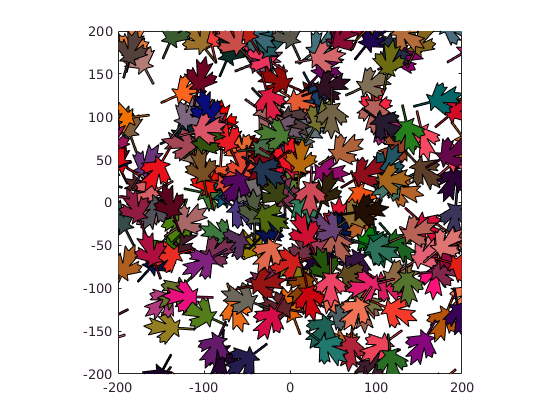

case 3
    %Translation
    u = [-80;60];
    F1=[F0(1,:)+u(1,1);F0(2,:)+u(2,1)];
    fill(F1(1,:),F1(2,:),'red');
    
    %Rotation
    n=300;
    for i=1:n 
        %rotation
        theta = 2*pi*rand();
        R = [cos(theta) -sin(theta);sin(theta) cos(theta)];
        F2=R*F1;
        
        %translation
        u = [-L+2*rand*L;-L+2*rand*L];
        F3=[F2(1,:)+u(1,1);F2(2,:)+u(2,1)];
        fill(F3(1,:),F3(2,:),[rand(),rand()/2,rand()/2]);
    end
    

end